# Numerical Analysis - Ex 5

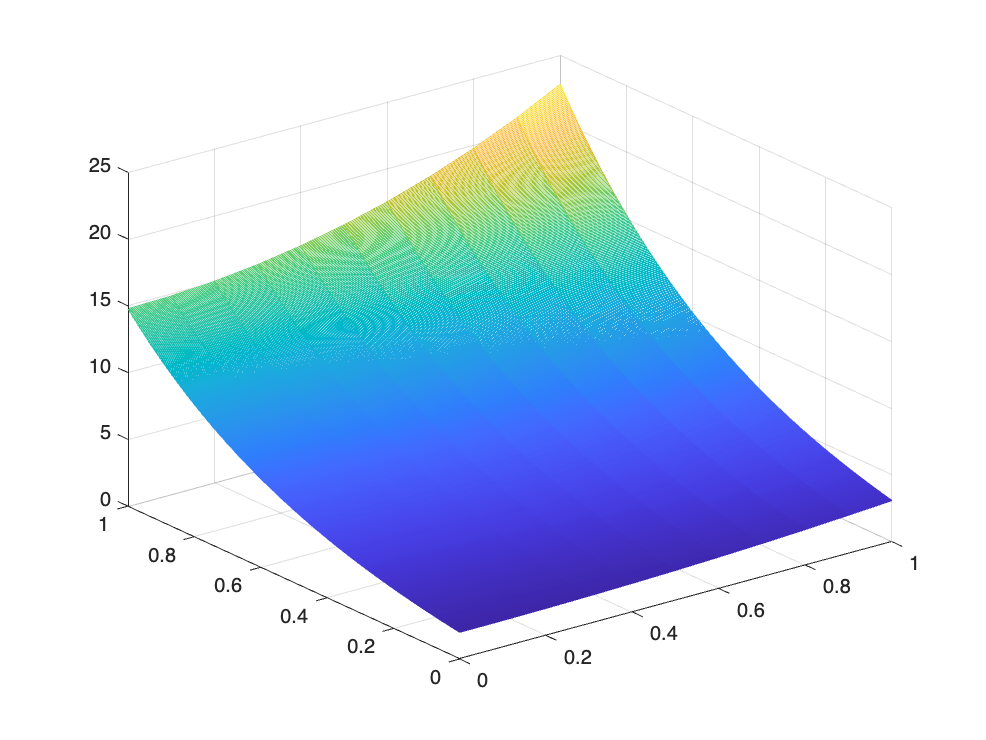

clear
%Problem 3
% u_t = 2*u_xx
% 0 =< x =< 1, 0 =< t =< 1
% With k >= 0.003,
% The forwaed difference method becomes unstable
h = 0.1;
k = 0.002;
M = 1/h;
N = 1/k;
D = 2;
f = @(x) 2*cosh(x);
l = @(t) 2*exp(2*t);
r = @(t) (exp(2) + 1)*exp(2*t - 1);
% Plot the approximation
w = heatfd(0, 1, 0, 1, M, N,D, f, l, r );

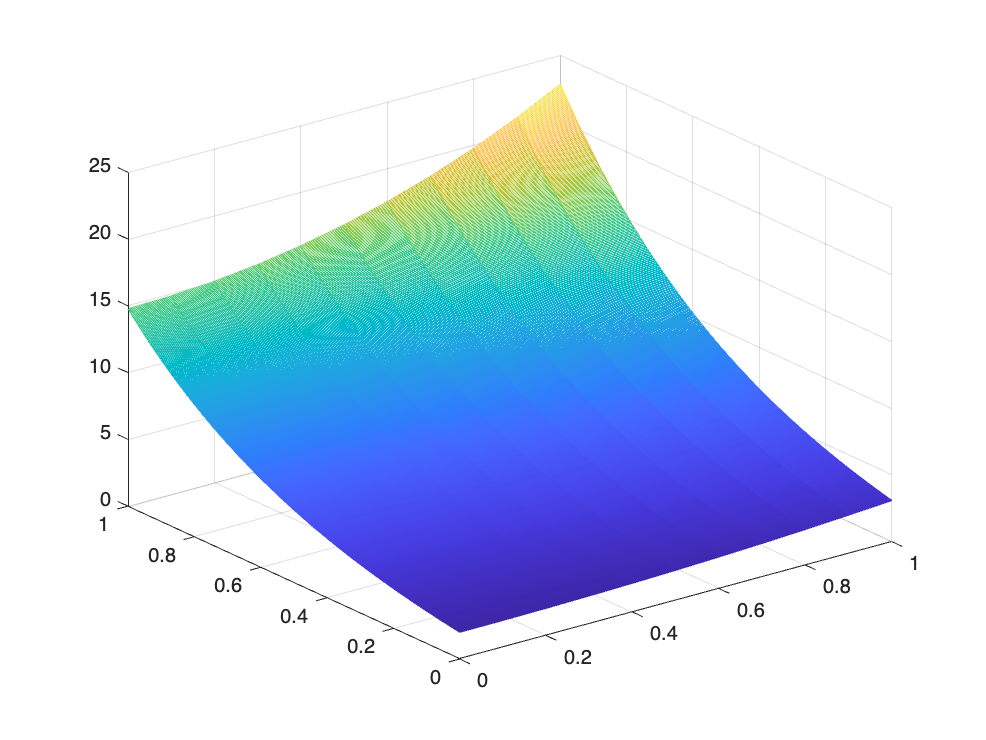


% Plot the exact solution
x = 0:h:1;
t = 0:k:1;
[x,t] = meshgrid(x,t);
exact = exp(2*t + x) + exp(2*t - x);
mesh(x,t, exact);


% Calculate mean square error between 
% exact solution and approximation
MSE = norm(w-exact,'fro')^2/numel(w)

MSE = 6.0596e-07

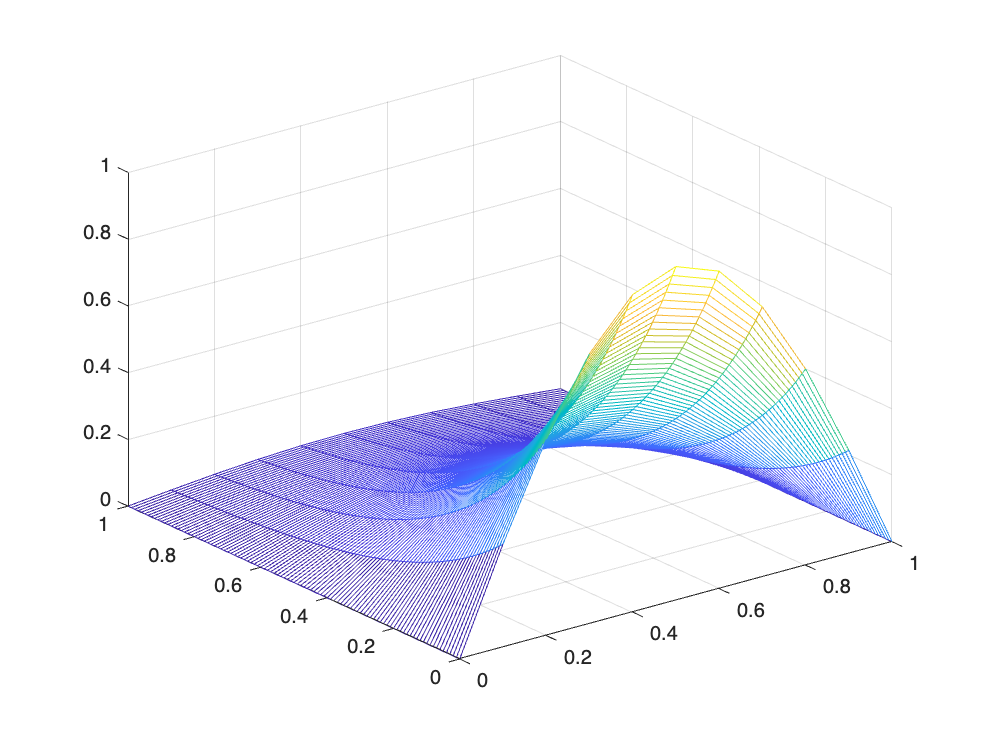

clear
%Problem 4
% pi*u_t = u_xx
% 0 =< x =< 1, 0 =< t =< 1
% After many trials, I realize
% with k>0.3, the Foward Difference Method
% become unstable
% So, the method stable when k =< 0.3
h = 0.1;
k = 0.01;
M = 1/h;
N = 1/k;
D = 1/pi;
f = @(x) sin(pi*x);
l = @(t) 0*t;
r = @(t) 0*t;
% Plot the approximation
w = heatfd(0, 1, 0, 1, M, N,D, f, l, r );

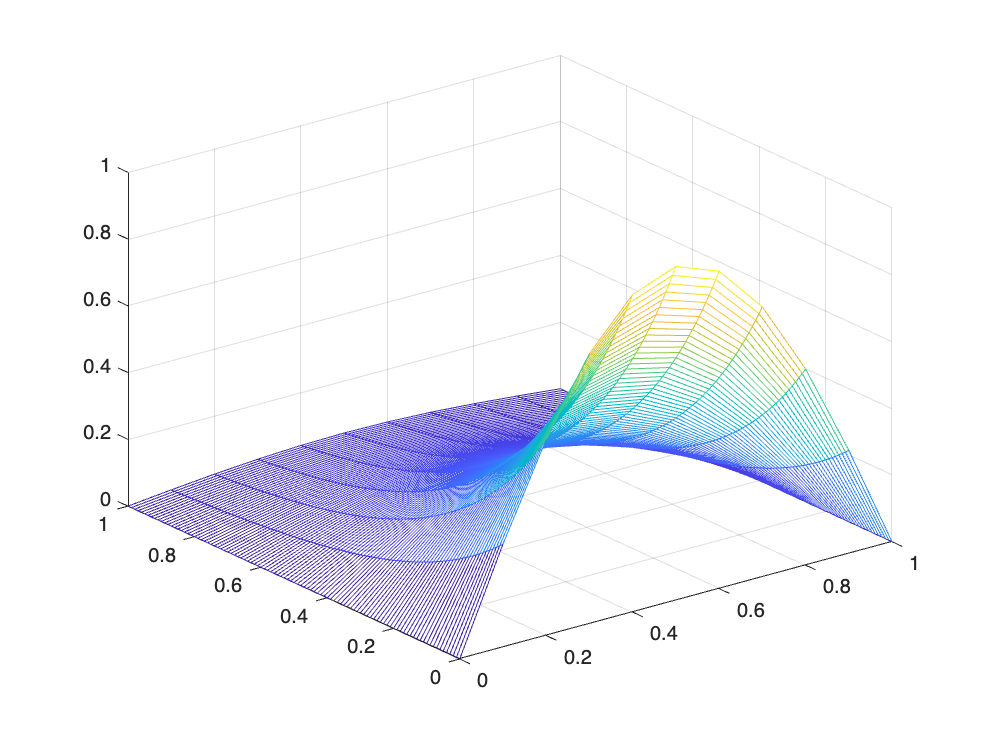


% Plot the exact solution
x = 0:h:1;
t = 0:k:1;
[x,t] = meshgrid(x,t);
exact = exp(-pi*t).*sin(pi*x);
mesh(x,t, exact);


% Calculate mean square error between 
% exact solution and approximation
MSE = norm(w-exact,'fro')^2/numel(w) 

MSE = 1.9372e-06

% Problem 5
A = [0,1;1,3/2];
[U, S, V] = svd(A)

U =    -0.4472   -0.8944
   -0.8944    0.4472


S =     2.0000         0
         0    0.5000


V =    -0.4472    0.8944
   -0.8944   -0.4472


% So, the best rank-one approximation
% is spanned by vector corresponding to
% largest singular value s1 = 2
% u1 = [-0.4472; -0.8944]
% replace s2 by zero
S1 = [2,0;0,0]

S1 =      2     0
     0     0


A1 = U*S1*V' % Best rank one approximation

A1 =     0.4000    0.8000
    0.8000    1.6000


function w=heatfd(xl ,xr ,yb ,yt ,M, N, D, f, l, r)
% Forward difference method for heat equation
% input: space interval [xl,xr], time interval [yb,yt],
% number of space steps M, number of time steps N
% output: solution w
% Example usage: w=heatfd(0,1,0,1,10,250)
h=(xr -xl)/M;
k=(yt-yb)/N ;
m=M-1; n=N;
sigma=D*k/(h*h);
a=diag(1-2*sigma*ones(m,1))+diag(sigma*ones(m-1,1),1);
a=a+diag(sigma*ones(m-1,1),-1); % define matrix a
lside=l(yb+(0:n)*k); rside=r(yb+(0:n)*k);
w(:,1)=f(xl+(1:m)*h) ; % initial conditions
for j=1:n
    w(:,j+1)=a*w(:,j)+sigma*[lside(j);zeros(m-2,1);rside(j)];
end

w=[lside;w;rside]'; % attach boundary conds
x=(0:m+1)*h;t=(0:n)*k;

mesh(x,t,w); % 3-D plot of solution w

end